# 1 Matlab Basic

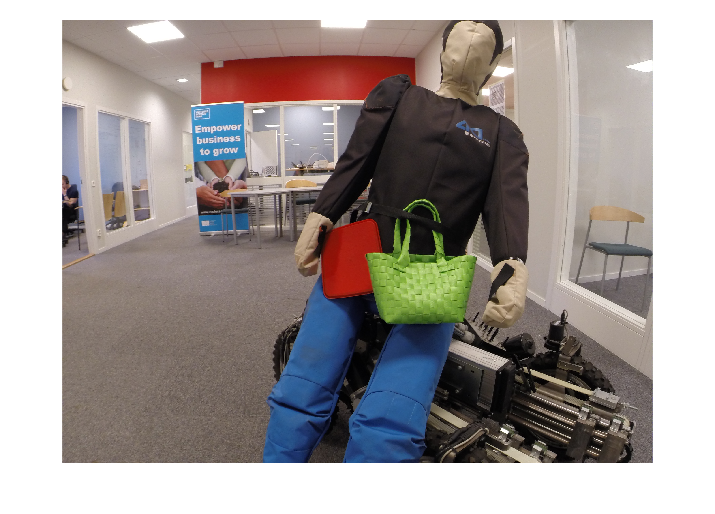

I = imread(['C:\Users\noben\OneDrive - Mälardalens högskola\Documents\GitHub\SesorTech-ELA400\img\bob.JPG']);
imshow(I);

imwrite(I, 'C:\Users\noben\OneDrive - Mälardalens högskola\Documents\GitHub\SesorTech-ELA400\img\bob_saved.png');

## 2 Image Representation

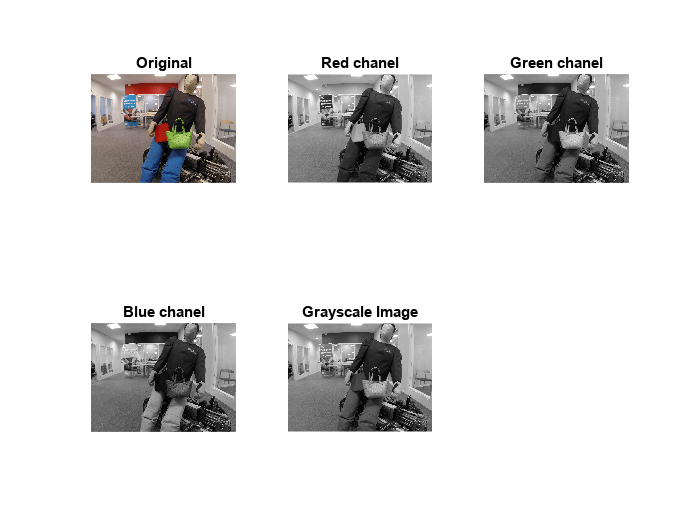

I = imread('C:\Users\noben\OneDrive - Mälardalens högskola\Documents\GitHub\SesorTech-ELA400\img\bob.JPG');
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

figure
subplot(2,3,1);
imshow(I);
title('Original');
subplot(2,3,2);
imshow(R);
title('Red chanel');
subplot(2,3,3);
imshow(G);
title('Green chanel');
subplot(2,3,4);
imshow(B);
title('Blue chanel');
subplot(2,3,5);
gray_img = rgb2gray(I);
imshow(gray_img);
title('Grayscale Image');

## 3 Threshold and Color Space

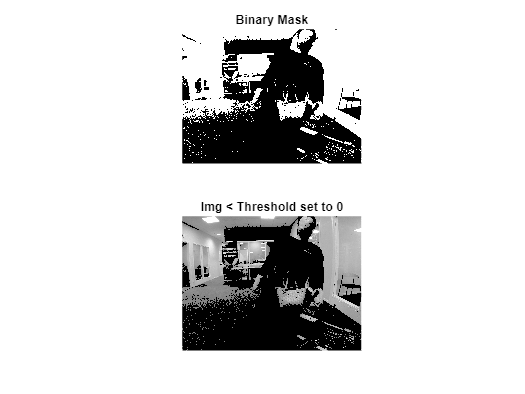

clc;
clear;

I = imread('C:\Users\noben\OneDrive - Mälardalens högskola\Documents\GitHub\SesorTech-ELA400\img\bob.JPG');
gray_img = rgb2gray(I);
thresholdValue = 128;

BinaryMask = gray_img > thresholdValue;
ThreshImg = gray_img;
ThreshImg(ThreshImg < thresholdValue) = 0;

figure;
subplot(2,1,1);
imshow(BinaryMask);
title('Binary Mask');
subplot(2,1,2);
imshow(ThreshImg);
title('Img < Threshold set to 0');

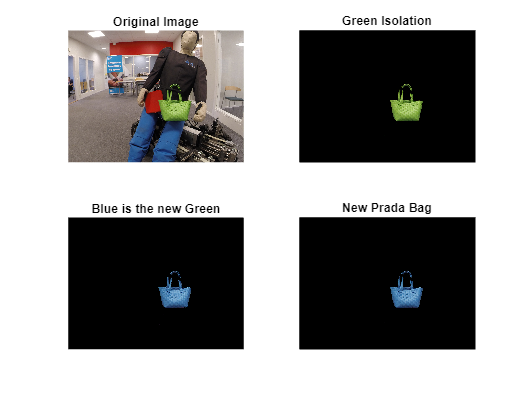


GreenFilt = I;
GreenFilt(:,:,1) = 0;
GreenFilt(:,:,3) = 0;
%GreenFilt(GreenFilt < thresholdValue) = 0;

% MATLAB COLOR THRESHOLD APP: HSV FUNCTION
HSV = rgb2hsv(I);
% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.192;
channel1Max = 0.473;
% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.320;
channel2Max = 1.000;
% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 1.000;
% Create mask based on chosen histogram thresholds
sliderBW = (HSV(:,:,1) >= channel1Min ) & (HSV(:,:,1) <= channel1Max) & ...
    (HSV(:,:,2) >= channel2Min ) & (HSV(:,:,2) <= channel2Max) & ...
    (HSV(:,:,3) >= channel3Min ) & (HSV(:,:,3) <= channel3Max);
BW_edge = sliderBW;
% Initialize output masked image based on input image.
maskedRGBImage = I;
% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW_edge,[1 1 3])) = 0;

% Convert to RGB to HSV -> change Hue(color) -> back to RGB
HSVPic = rgb2hsv(maskedRGBImage);
HSVPic(:,:,1) = mod(HSVPic(:,:,1) + 0.35, 1);  % +0.35(around 100 degrees on colorwheel) look at HSV App
HueChange = hsv2rgb(HSVPic);

% Add color change on original image

figure
subplot(2,2,1);
imshow(I);
title('Original Image');
subplot(2,2,2);
imshow(maskedRGBImage);
title('Green Isolation');
subplot(2,2,3);
imshow(HueChange);
title('Blue is the new Green');
subplot(2,2,4);
imshow(HueChange);
title('New Prada Bag');

## 4 Spatial operator and convolution

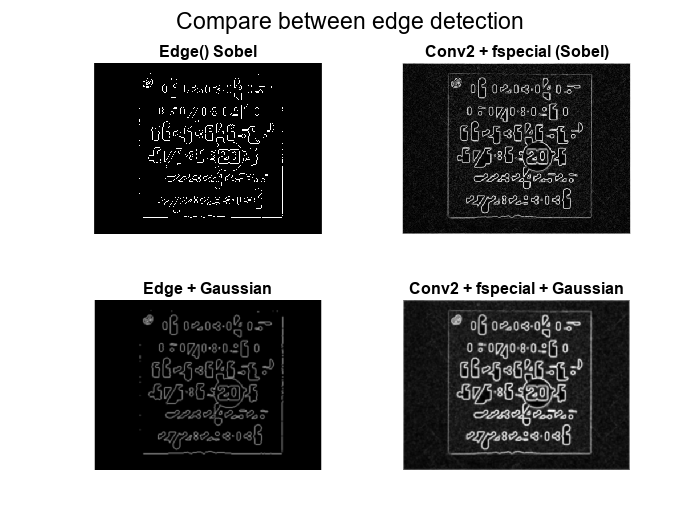

clc;
clear;
I = imread("C:\Users\noben\OneDrive - Mälardalens högskola\Documents\GitHub\SesorTech-ELA400\img\calendar_speckle10.jpg") ;
Idoub = im2double(I);

% --- MATLAB built in edge-functions ---
BW_edge = edge(Idoub,"sobel");
BW_edge_blurred = imgaussfilt(double(BW_edge),1);

% --- Own convolution edgedetection ---
sobel_x = fspecial('sobel');
sobel_y = sobel_x';
Ix = conv2(Idoub, sobel_x, 'same');
Iy = conv2(Idoub, sobel_y, 'same');
gradmag = sqrt(Ix.^2 + Iy.^2);
gradmag_norm = gradmag / max(gradmag(:));
gauss_filter = fspecial('gaussian', [5 5], 1);
gradmag_blurred = imfilter(gradmag_norm, gauss_filter, 'same');

% --- Plot Result ---

figure;
sgtitle('Compare between edge detection');
subplot(2,2,1);
imshow(BW_edge);
title('Edge() Sobel');
subplot(2,2,2);
imshow(gradmag, []);
title('Conv2 + fspecial (Sobel)');
subplot(2,2,3);
imshow(BW_edge_blurred);
title('Edge + Gaussian');
subplot(2,2,4);
imshow(gradmag_blurred, []);
title('Conv2 + fspecial + Gaussian');


sobel = fspecial('sobel');
gauss = fspecial('gaussian', [5 5], 1);
n = 1000;
% A = (I*s)*g Img*sobel then * gauss
tic
for i = 1:n
    temp = conv2(Idoub, sobel, "same");
    A = conv2(temp, gauss,"same");
end
tA = toc;

% B = I*(s*g) combine sobel + gauss then one instance of conv with img
% Sobel + Gauss creates a new filter that we use instead for faster conv
sob_Gauss = conv2(sobel,gauss, "same");
tic
for i = 1:n
    B = conv2(Idoub, sob_Gauss, "same");
end
tB = toc;

disp(['Time A:',num2str(tA)]);

Time A:0.56693


disp(['Time B:',num2str(tB)]);

Time B:0.19142


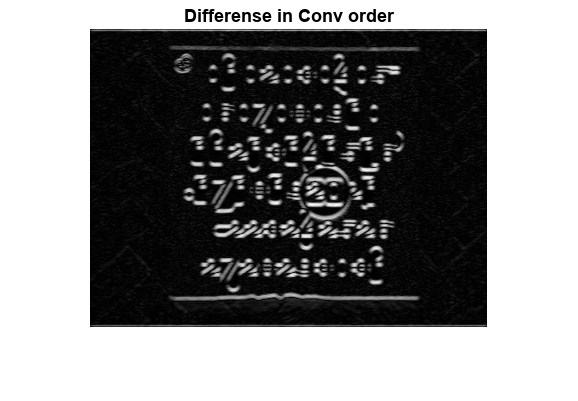

diff = abs(A - B);

figure;
imshow(diff, []);
title('Differense in Conv order');

## 5 Calibration and Measurement